clear
load("V1.mat");
load("Vout.mat");
Vdm = V1;

[first, last, mmax, bmax, Nmax] = linefit(Vdm(95:120), Vout(95:120), 5e-3)

first = 1

last = 6

mmax = 43.4571

bmax = 4.0749

Nmax = 6

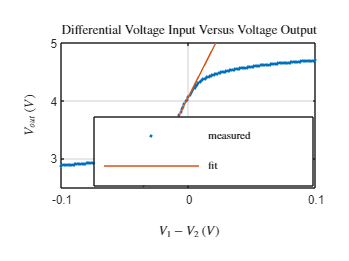


plot(Vdm, Vout,'.');
hold on;
plot(Vdm, Vdm*mmax + bmax);
grid on;
ylim([2.5,5])
title("Differential Voltage Input Versus Voltage Output","Interpreter","latex")
xlabel("$V_{1}-V_{2}$ ($V$)","Interpreter","latex")
ylabel("$V_{out}$ ($V$)","Interpreter","latex")
legend("measured","fit","Interpreter","latex","Location","best")
hold off;